% Emmanuelle

% Script to fit diameter change

load('DataToFit.mat');
load('Time.mat');

TStim = 10;                     % (in s)
Tstop = 35;                     % (in s)
ThresholdLevel = 0.1;           % (between 0 and 1)

% Data Fit

IndexAfterBaseline = (Time>=TStim) & (Time<=Tstop);
[xData, yData] = prepareCurveData( Time(IndexAfterBaseline), DataToFit(IndexAfterBaseline));

% Set up fittype and options.
ft = fittype( 'a0/(1+(exp(-(x-x0)/T0)))+a1/(1+(exp((x-x1)/T1)))+c', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [0 0 0 0 -Inf 0 0];
opts.StartPoint = [3 0.699076722656686 0.959743958516081 0.585267750979777 0.118997681558377 12 25];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts )

fitresult =      General model:
     fitresult(x) = a0/(1+(exp(-(x-x0)/T0)))+a1/(1+(exp((x-x1)/T1)))+c
     Coefficients (with 95% confidence bounds):
       T0 =       2.351  (2.105, 2.598)
       T1 =       1.766  (1.582, 1.95)
       a0 =        5.67  (5.152, 6.189)
       a1 =       5.227  (4.723, 5.731)
       c =      -5.309  (-5.886, -4.733)
       x0 =       18.77  (18.44, 19.11)
       x1 =       28.01  (27.78, 28.24)

gof = struct with fields:
           sse: 6.0691
       rsquare: 0.9900
           dfe: 244
    adjrsquare: 0.9898
          rmse: 0.1577


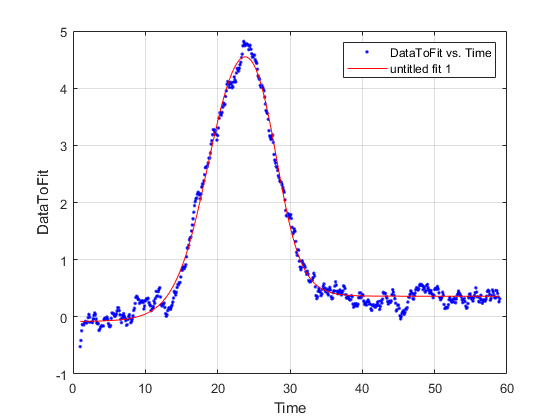

fitcoeffvals= coeffvalues(fitresult);

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, Time, DataToFit );
legend( h, 'DataToFit vs. Time', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );

% Label axes
xlabel( 'Time', 'Interpreter', 'none' );
ylabel( 'DataToFit', 'Interpreter', 'none' );
grid on


% fitcoefvalues
T0 = fitcoeffvals(1) 

T0 = 2.3513

T1 = fitcoeffvals(2)

T1 = 1.7660

a0 = fitcoeffvals(3)

a0 = 5.6704

a1 = fitcoeffvals(4)

a1 = 5.2270

c = fitcoeffvals(5)

c = -5.3095

X0 = fitcoeffvals(6)

X0 = 18.7742

X1 = fitcoeffvals(7)

X1 = 28.0087

% Time threshold calculation  

TTime = (0:0.01:60)';
FitTTime = FitDiameterFunction(fitcoeffvals, TTime);

[MaxFit, IdxMax] = max(FitTTime)

MaxFit = 4.5482

IdxMax = 2380

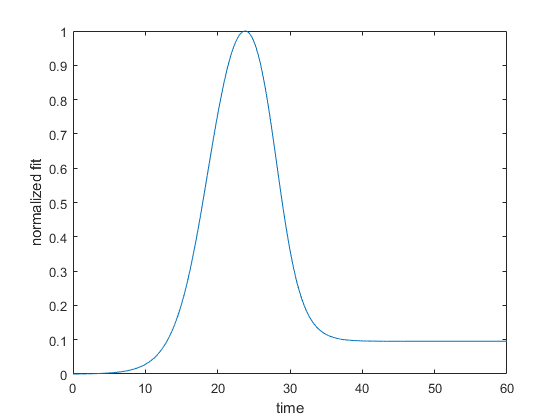

NormFit = (FitTTime - min(FitTTime(1:IdxMax))) / (MaxFit - min(FitTTime(1:IdxMax)));

% plot noorm fit 
figure( 'Name', 'Normalized Fit' );
h2 = plot( TTime, NormFit );
% Label axes
xlabel( 'time', 'Interpreter', 'none' );
ylabel( 'normalized fit', 'Interpreter', 'none' );


IndexBelowThreshold = (NormFit <= ThresholdLevel);
IndexBeforeMax = IndexBelowThreshold(1:IdxMax);
TimeBeforeThreshold = TTime(IndexBeforeMax);
[TimeThrehold, IdxTimeThrehold] = max(TimeBeforeThreshold);
TimeThrehold;

IndexBelowThreshold10 = (NormFit <= 0.1);
IndexBeforeMax10 = IndexBelowThreshold10(1:IdxMax);
TimeBeforeThreshold10 = TTime(IndexBeforeMax10);
[TimeThrehold10, IdxTimeThrehold10] = max(TimeBeforeThreshold10);
TimeThrehold10

TimeThrehold10 = 13.0900


IndexBelowThreshold15 = (NormFit <= 0.15);
IndexBeforeMax15 = IndexBelowThreshold15(1:IdxMax);
TimeBeforeThreshold15 = TTime(IndexBeforeMax15);
[TimeThrehold15, IdxTimeThrehold15] = max(TimeBeforeThreshold15);
TimeThrehold15

TimeThrehold15 = 14.1500


IndexBelowThreshold20 = (NormFit <= 0.2);
IndexBeforeMax20 = IndexBelowThreshold20(1:IdxMax);
TimeBeforeThreshold20 = TTime(IndexBeforeMax20);
[TimeThrehold20, IdxTimeThrehold20] = max(TimeBeforeThreshold20);
TimeThrehold20

TimeThrehold20 = 14.9400


TimeThrehold101520 = [TimeThrehold10 ; TimeThrehold15 ; TimeThrehold20];


function y = FitDiameterFunction(fitcoeffvals, x)
y = fitcoeffvals(3)./ (1 + exp(-(x-fitcoeffvals(6))/fitcoeffvals(1)))...
    + fitcoeffvals(4)./ (1 + exp((x-fitcoeffvals(7))/fitcoeffvals(2)))...
    + fitcoeffvals(5);
end